# Generalized Conway's Game of Life

## 設定

- T                ：シミュレーション回数

- n                ：エリアのサイズ

- d                ：近傍の半径

- alive_min   ：近傍の生存セル数の最小値（生存）

- alive_max  ：近傍の生存セル数の最大値（生存）

- birth_min   ：近傍の生存セル数の最小値（誕生）

- birth_max  ：近傍の生存セル数の最小値（誕生）

- movie        ：動画の表示の有無

- resize        ：保存画像のリサイズの有無


%Parameters
T = 560;
n = 1000;
d = 60;
alive_min = 0.1352;
alive_max = 0.3474;
birth_min = 0.2447;  
birth_max = 0.3543;
sigma     =  0;
exit_conditions = -1;
movie = true;
resize = true;

## 実行

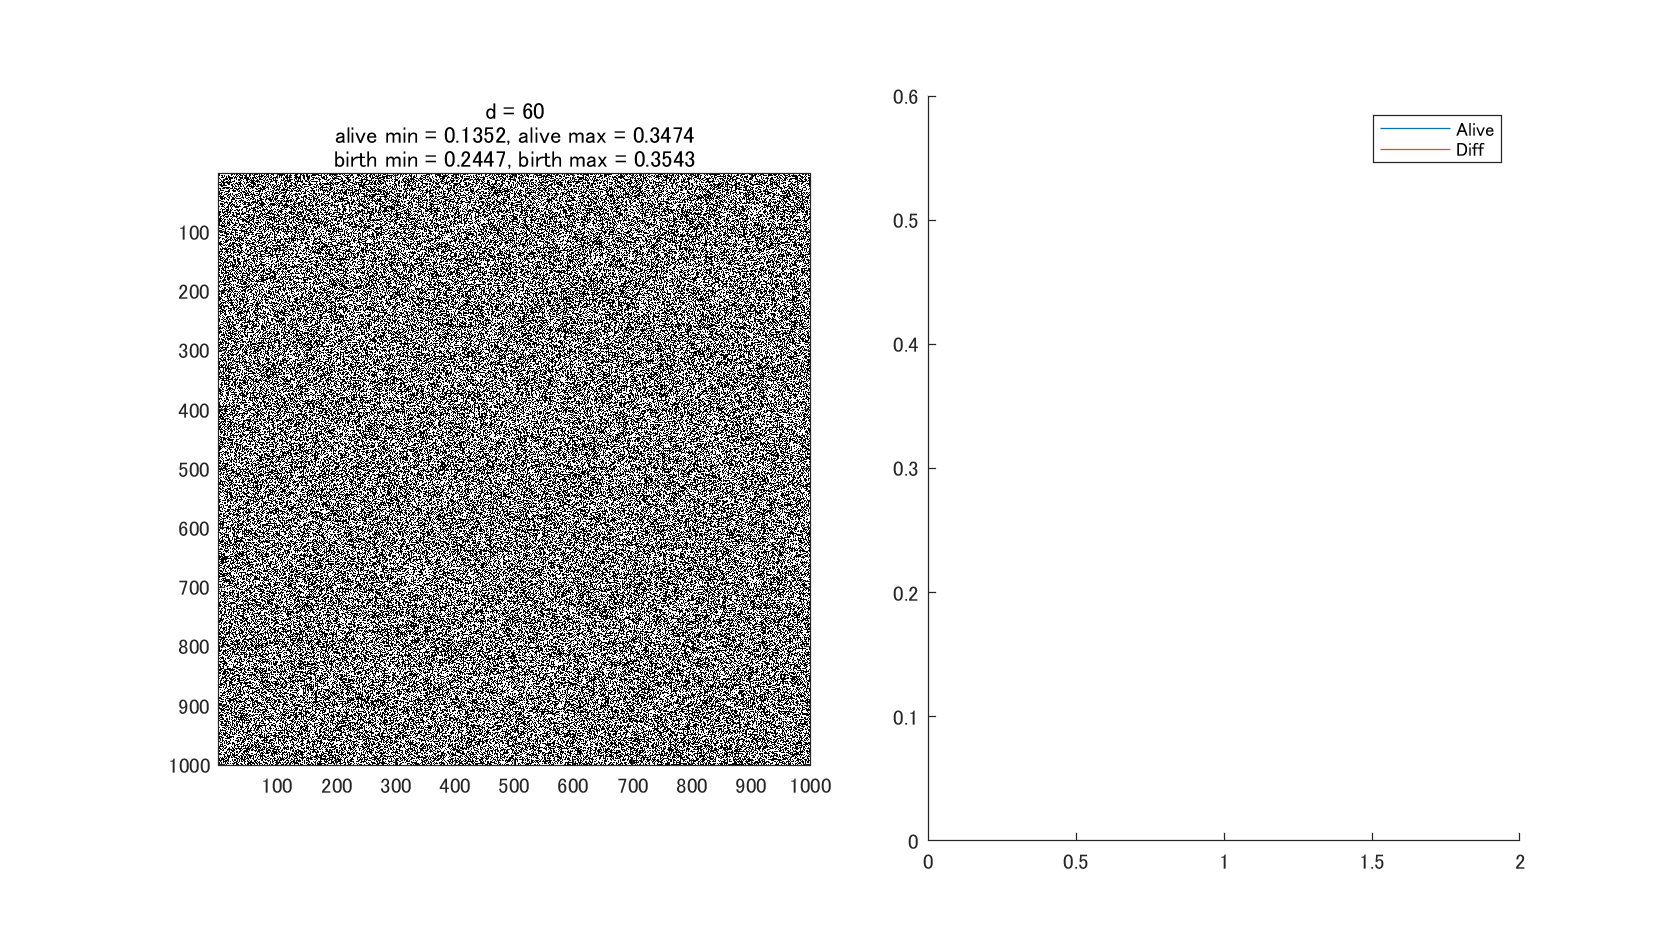

配列インデックスは正の整数または logical 値でなければなりません。

'xlim' が関数と変数の両方として存在しています。これが意図的でない場合は、'clear xlim' を使用して変数 'xlim' をワークスペースから削除してください。

M = rand(n) > 0.5;

alive = zeros(T+1,1);
alive(1) = sum(M,"all");
diff_alive = zeros(T+1,1);
diff_alive(1) = 0;

tic
figure("Position",[0,0,1920/2,1080/2]);
for t = 1:T
    %Visualize
    if movie == true
        cla
        tiledlayout(1,2,"TileSpacing","compact")
        nexttile;
        imagesc(M*255);    
        colormap gray 
        pbaspect([1 1 1]);
        title(["d = "+num2str(d) ...
               "alive min = "+num2str(alive_min)+", alive max = "+num2str(alive_max) ...
               "birth min = "+num2str(birth_min)+", birth max = "+num2str(birth_max)])
        nexttile;
        hold on
        plot(alive(1:t)./n^2);
        plot(diff_alive(1:t)./n^2);
        legend(["Alive","Diff"]);
        xlim([-inf inf]);
        ylim([0 1]);
        xlabel("Time");
        ylabel("Rate")
        hold off
        drawnow
    end
    
    A = ones(2*d+1).*(1+normrnd(0,sigma,2*d+1));
    A(d+1,d+1) = 0;
    Asum = sum(A,"all");
    
    temp = conv2(padarray(M,[d,d],0,'circular'),A,"same");
    S = temp(d+1:n+d,d+1:n+d);
    M_next = M.*(alive_min<=Asum.*S).*(S<=Asum.*alive_max)+...
        (1-M).*(Asum.*birth_min<=S).*(S<=Asum.*birth_max);
    
    alive(t+1) = sum(M_next,"all");
    diff_alive(t+1) = sum(abs(M-M_next),"all");
    
    if sum(abs(M-M_next)./n^2,"all") < exit_conditions
        break
    end
    
    M = M_next;
end

clf
image(M*255);    colormap gray 
pbaspect([1 1 1]);
title(["d = "+num2str(d), ...
       "alive min = "+num2str(alive_min)+", alive max = "+num2str(alive_max) ...
       "birth min = "+num2str(birth_min)+", birth max = "+num2str(birth_max)])
imwrite(imresize(M*255,[1024,1024],"nearest"),"result.png");

## 参考文献

[1]  Wikipedia, ライフゲーム

[https://ja.wikipedia.org/wiki/%E3%83%A9%E3%82%A4%E3%83%95%E3%82%B2%E3%83%BC%E3%83%A0](https://ja.wikipedia.org/wiki/%E3%83%A9%E3%82%A4%E3%83%95%E3%82%B2%E3%83%BC%E3%83%A0)